# Spectrogram - When the Frequency Changes Over Time

Brandon Armstrong

MathWorks, Training Services

Created for *Differential Equations: Fourier Series and Partial Differential Equations* on edX.

While this script focuses on an audio signal that changes in time, many of the concepts discussed are general considerations for processing time domain data and performing Fourier transforms. **This is not required** and no exercises will rely on material presented here. However, if you're interested in learning a little more about signal processing, this script will introduce you to concepts closely related to work done in class.

## What is a spectrogram?

We've shown in lecture and in the examples how we can use a Discrete Fourier Transform to find the frequencies found in time domain data. The Fourier transform is useful for periodic signals, but what if the frequency of the signal changes over time? In fact, to avoid this question, we've been extracting only a small part of the audio signals for analysis. 

You might guess that we could divide up our signal into small chunks and perform a Fourier transform on each chunk...well, good guess! By finding Fourier transform on small chunks of the signal, we can create an image where one axis represents the frequency information, the 2nd axis is time, and the color is the power (or intensity) of the frequency for that time. This image is called a spectrogram. 

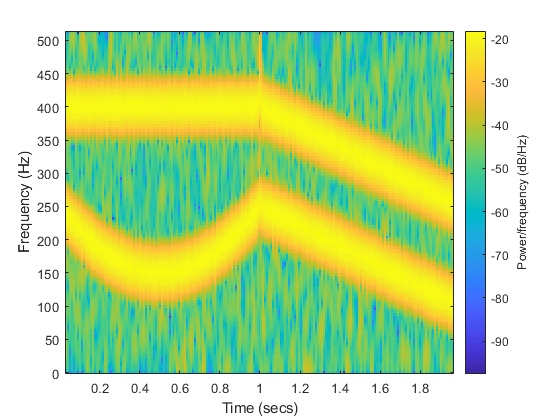

If the above description was all there was to the story, we'd probably just point you to the spectrogram documentation and tell you to explore. However, unless you're already pretty familiar with signal processing, you may find all the different inputs and calling syntaxes confusing. The point of this script is to help demystify the inputs. This will not only help us understand spectrograms, but also give us more insight into Fourier transforms in the process.

### A signal that changes in time

Many example files are included with MATLAB. One audio file is "splat." When we load splat, two variables are imported to our MATLAB workspace: 

- the audio data in the variable `y` 

- the sampling frequency in variable `Fs`. Here, Fs = 8192 Hz.

Run this section to load the data and listen to splat.

load splat
sound(y, Fs)

Clearly the frequency content of the sound changes over the time of the recording. But do we really need a spectrogram? Run this section to compute the discrete Fourier transform as shown in class and see the results.

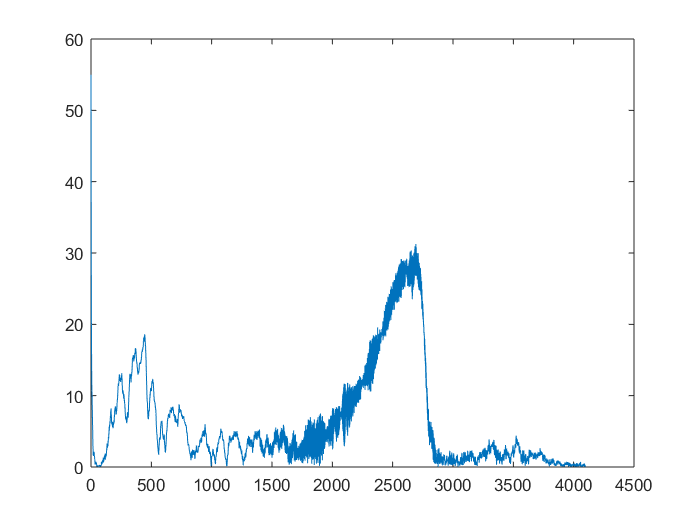

Y = fft(y);
Ymag = abs(Y);
N = length(Y);
f = 0:Fs/N:Fs/2;
Ymag = Ymag(1:length(f));
plot(f, Ymag)

Clearly there is something around 2500 Hz, but the peak is very broad and noisy. Is the low frequency content the splat at the end, or something else? Without the time information, we're missing a big chunk of the story. 

### Create a spectrogram

To begin, we'll just create a spectrogram as described in the introduction. Then we'll go through the inputs to learn more about discrete Fourier Transforms and see if we can do better. The code below breaks the signal `y` into separate chunks of 128 points and calculates the FFT for each.

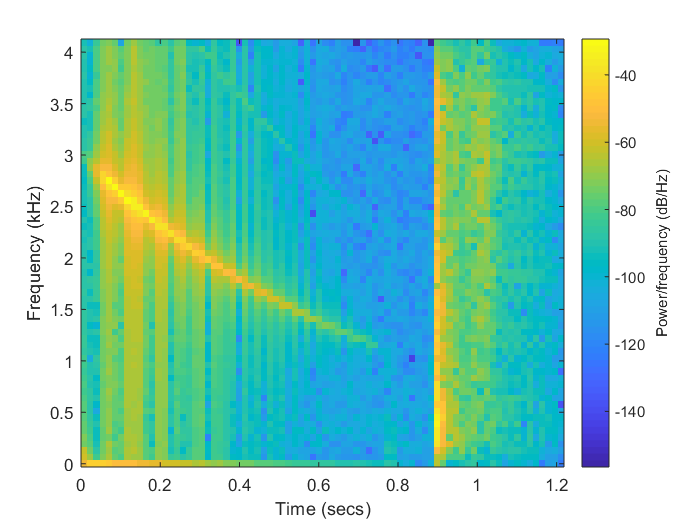

spectrogram(y, ones(128,1), 0, 128, Fs, 'yaxis')

Great, we can see a bright frequency band starting at about 2750 Hz and decreasing in frequency over time. There is also a higher frequency band appearing near 0.4s, but it is of low intensity (notice that we see no corresponding peak in the FFT plotted above!). It looks like the splat occurred near 0.9 seconds. However, it appears that there is fairly strong frequency content across all frequencies within the Nyquist frequency. Is this correct or is something else going on?

## Windowing

The second input to the `spectrogram` function specifies how to window the data. When we use a vector, as we did above, the length of the vector specifies the number of points to use in each chunk of data, and the values of the window vector are multiplied by the corresponding point in the chunked data before computing the Fourier transform. For example

`data2FFT = window .* dataInCurrentWindow;`

Above, our window was simply a vector 1's, or a rectangular window. Thus, the FFT was performed on the raw data, but in most cases this is not the best way find the frequency data as we'll show below.

### The Rectangular Window

In class, we've applied the `fft` function directly on the data. We can think of this as applying a rectangular window to the data, meaning we multiply each data point by 1, and then take the FFT. Let's look at the FFT of a rectangular window.

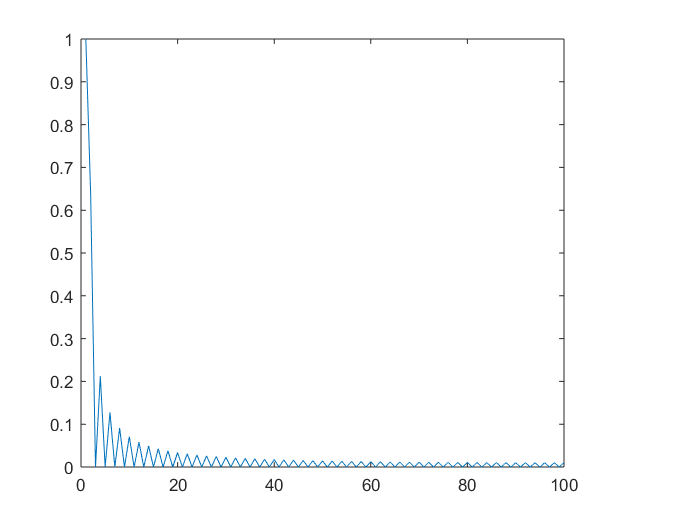

r = [zeros(1,50), ones(1, 100), zeros(1, 50)];
rFT = abs(fft(r));
rFT = rFT./max(rFT); 
plot(rFT(1:100)) 

The FFT of the rectangular window has significant frequency content outside of 0. Basically, when cutting off a sine wave with a rectangular pulse, we are introducing frequency content into the FFT that does not exist 

### The Hamming Window

Notice that we had to specify a vector of ones as the 2nd input to `spectrogram` to get rectangular window. We did this because it matched our initial description of what a spectrogram is, but it is not the default MATLAB behavior and usually other windows are used. The default behavior is to use a Hamming window. With a Hamming window, we multiply each point in the time domain by the value of the Hamming window, then take the Fourier transform. 

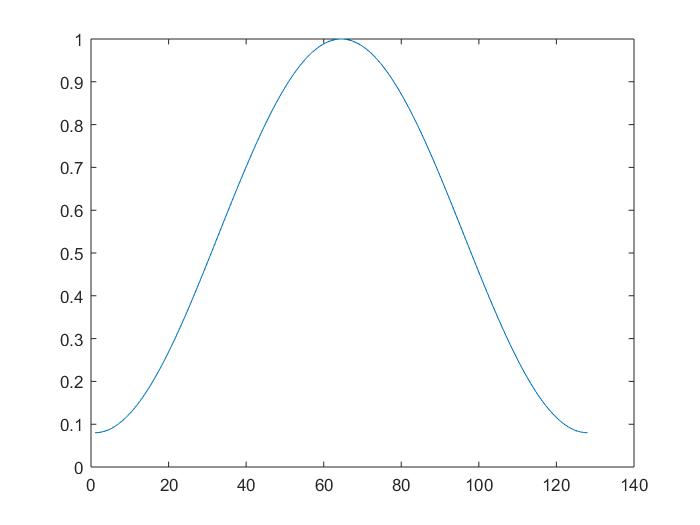

w = hamming(128); % a 128 point Hamming window;
plot(w)

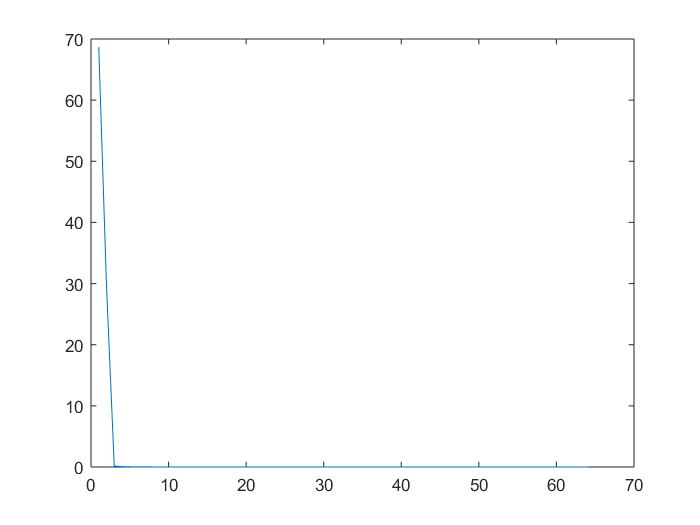

wFT = abs(fft(w));
plot(wFT(1:64))

Notice how the Fourier transform of the Hamming window approaches 0 much better than the Fourier transform of the rectangular window. Let's take a small segment of our data and compare the two windows. For example, by inspecting the spectrogram above and doing some math with Fs, we see that 0.1328 s has strong frequency content, which corresponds to point 1088 in the data. Let's look at a 128 point window about this point.

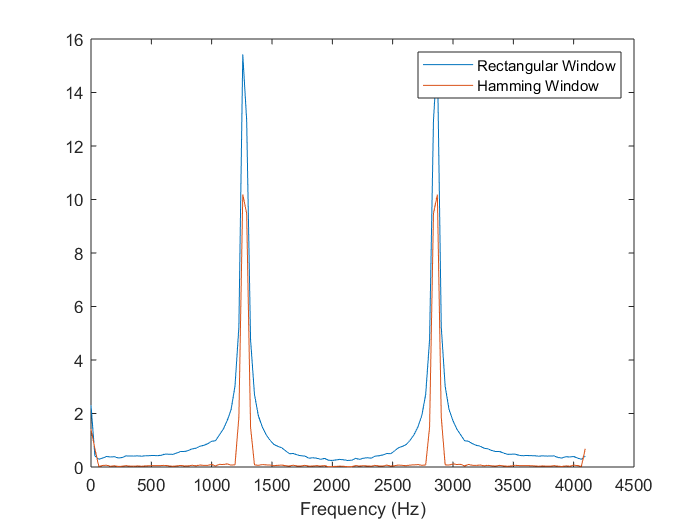

% Get a 128 point segment of our original signal and create the frequency
% axis
signal = y(1088-64:1088+63);
f = linspace(0, Fs/2, length(signal));
% Take the fft with a rectangular window, just the data
rectSignalFT = abs(fft(signal));
% Create a 128 point Hamming window
h = hamming(128); 
% Multiply the signal by the Hamming window, then perform the FFT
hammingSignalFT = abs(fft(h.*signal));
% Get the signle sided-spectrum for both and plot the results.
rectSignalFT = rectSignalFT(1:length(f));
hammingSignalFT = hammingSignalFT(1:length(f));
plot(f, rectSignalFT);
xlabel('Frequency (Hz)')
hold on
plot(f, hammingSignalFT);
legend({'Rectangular Window', 'Hamming Window'})
hold off

Notice how the rectangular window is much winder and more intense at the base of the peak than the Hamming window. This is why our first spectrogram appeared to have some strong frequency content across the entire spectrum. *The way we chunked the data introduced some frequency content!* 

### Spectrogram with a Hamming Window

Let's redo the spectrogram using the default Hamming window. First, we'll replot our spectrogram with a rectangular window so we don't need to scroll to compare. 

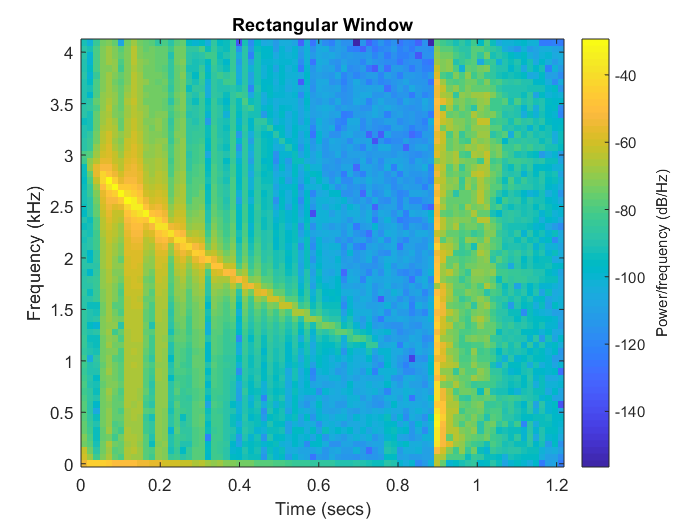

spectrogram(y, ones(128,1), 0, 128, Fs, 'yaxis')
title('Rectangular Window')

Since we're using the default behavior, we only have to specify how many points we want to include in the window. For other windows, we must specify a vector that is the shape of the window. 

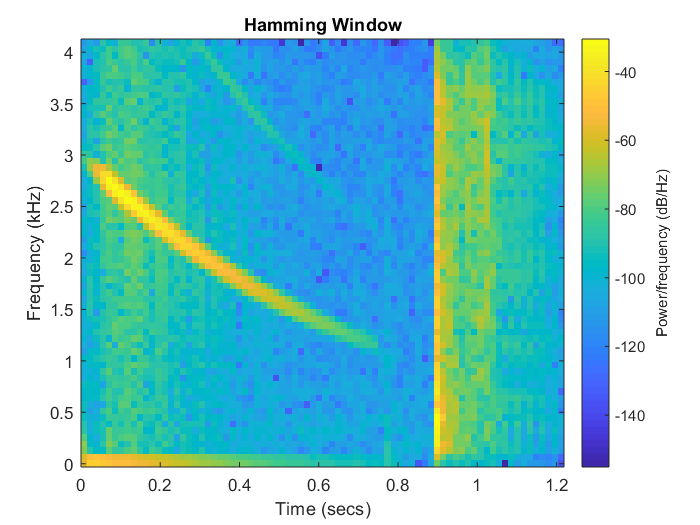

spectrogram(y, 128, 0, 128, Fs, 'yaxis')
title('Hamming Window')

Notice how the bands in the frequency axis are greatly reduced and the peak is more prominent with the Hamming window. However, you may also notice that the peak looks wider in the frequency domain with the Hamming window as opposed to the rectangular window. This is the cost of reducing the unwanted frequencies introduced by the rectangular window and is something one must consider when choosing a window!

### Choosing a Window 

There are a couple things to think about when choosing the size of the window. 

- How big should the window be?

- What type of window should we use?

#### How big should the window be?

Let's start with question 1. To answer this, we actually have two more questions:

- How rapidly is the signal changing?

- What frequency resolution is required?

In the above example, our window size was 128 points. The time of our window is given by $dt = N/Fs$ where N is the number of points in the window. So, for the above example, we have $128/8192 = 15$ ms. Is this fast enough? The spectrogram seems reasonable, suggesting 128 points might be appropriate. But you could be asking, why not go shorter? In the ideal case we get the instantaneous frequency information, right? If we don't know what time resolution we need, we might be tempted to go shorter.

That brings us to question 2. We can only resolve frequencies that are separated by more than $Fs/N$, in this example, that's 64 Hz. Depending on our signal and application, this may or may not be acceptable. 

- *In general, increasing the window size improves frequency resolution, but at the cost of time-resolution. *

However, recall that when we plotted the Fourier transform for the entire signal, we ended up with a large, very broad peak. 

- *Increasing the window will not improve resolution if the signal changes much inside the window.*

#### What type of window should we use?

A detailed discussion of how to choose a specific window shape, such a Hamming, is beyond the scope of this discussion. If you're interested to learn what windows are available, check out the online help: [https://www.mathworks.com/help/signal/ug/windows.html.](https://www.mathworks.com/help/signal/ug/windows.html.) Here, we'll make a few comments regarding windows.

- *Many windows reduce signal amplitude*. This does not necessarily mean they reduce the signal-to-noise ration (SNR), but if knowing the absolute amplitude of your signal is important or your signal has low SNR to begin with, this is an important consideration. We saw the effect of reduced amplitude with the hamming window above.

- *Windows may increase the peak width*. Signals do not have instantaneous start and stop points, and these rates contribute to the peak width. If your application requires analysis of peak width you'll need to take care when choosing a window. 

So, we see that there are pros and cons. The rectangular window may introduce unwanted frequencies but maintains amplitude and width. Applying a window can remove the unwanted frequencies but can reduce peak amplitude and increase peak width.

## Overlapping Windows

The third argument to the `spectrogram` function is the number overlap points as we move the window through the signal. We used 0 in our examples above meaning the first window included points 1 - 128 of the signal, the second window points 129 - 256, and so on. The result is that we see discontinuities in the spectrogram. We also risk missing some features, particularly if they are short lived. Let's look at an example.

### Example of Non-overlapping Windows

The code below creates a 1000 Hz sin wave with a 1500 Hz sin wave that appears briefly (noise was added as well). The code splits the data into two, non-overlapping, Hamming windows and computes the Fourier transform of each window. Notice how the 1500 Hz signal is barely present in either window!

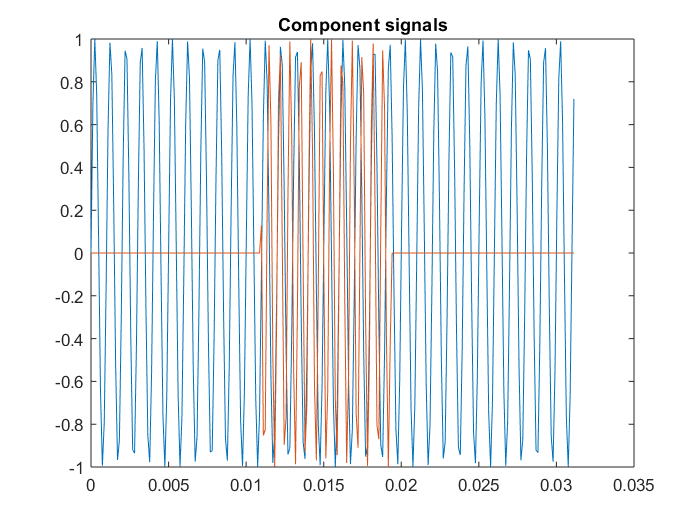

% Create a time vector and two signals
t = 0:1/Fs:255/Fs;
s1 = sin(2*pi*1000*t);
s2 = sin(2*pi*1500*t);
% Set the beginning and end of signal 2 to 0 so that it only briefly
% appears
s2([1:90, 160:end]) = 0;
plot(t, s1, t, s2)
title('Component signals')

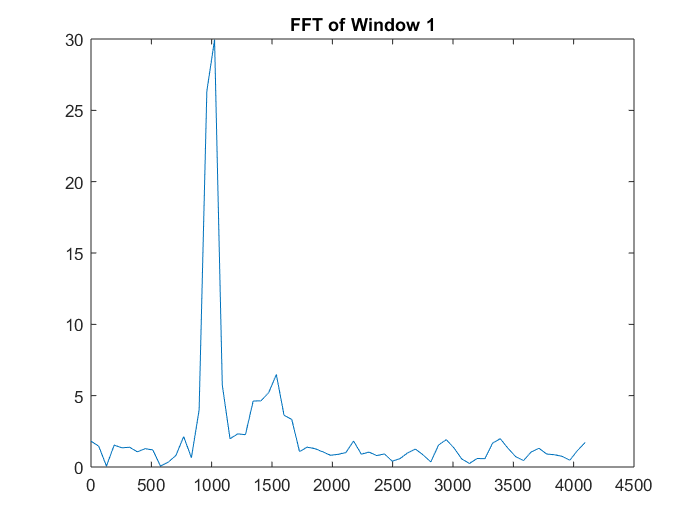


% Add the two signals together with noise
signal = s1 + s2 + 0.5*rand(1, 256) - 0.25;

% Create and apply a Hamming filter to each window
h = hamming(128)';
window1 = h.*signal(1:128);
window2 = h.*signal(129:end);

% Get the single-sided FFT for each window and plot
w1Mag = abs(fft(window1));
w2Mag = abs(fft(window2));
f = 0:Fs/128:Fs/2;
w1Mag = w1Mag(1:length(f));
w2Mag = w2Mag(1:length(f));

plot(f, w1Mag); title('FFT of Window 1')

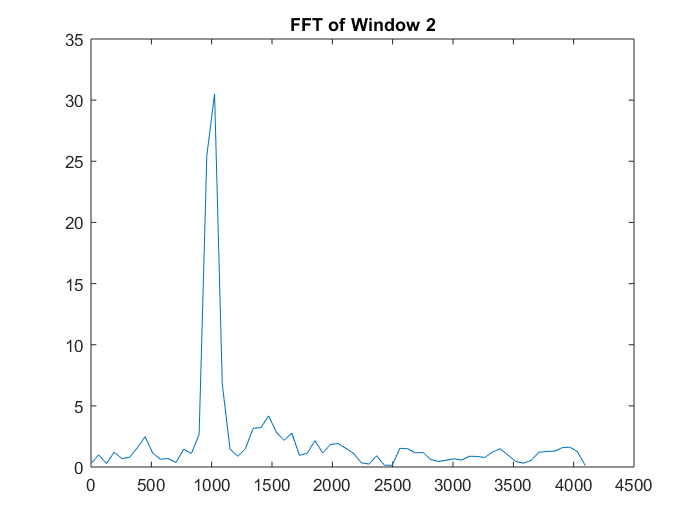

plot(f, w2Mag); title('FFT of Window 2')

### Example of Overlapping Windows

Now, let's repeat the same analysis, but have our windows overlap by 50%. This means we'll have 3 windows across the same signal. Looking at the results below we see that the first and third window still only show a weak peak at 1500 Hz, but now window 2 shows both peaks with near equal amplitude, just as we expect!

window1 = h.*signal(1:128);
window2 = h.*signal(65:192);
window3 = h.*signal(129:end);

% Get the single-sided FFT for each window and plot
w1Mag = abs(fft(window1));
w2Mag = abs(fft(window2));
w3Mag = abs(fft(window3));
f = 0:Fs/128:Fs/2;
w1Mag = w1Mag(1:length(f));
w2Mag = w2Mag(1:length(f));
w3Mag = w3Mag(1:length(f));

plot(f, w1Mag); title('FFT of Window 1')

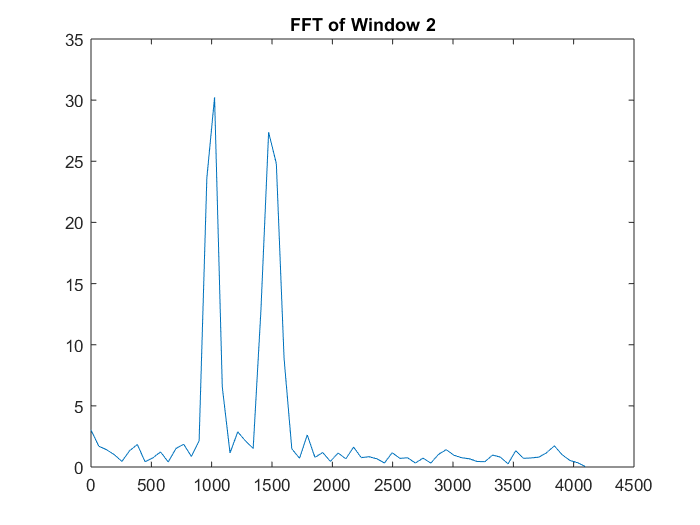

plot(f, w2Mag); title('FFT of Window 2')

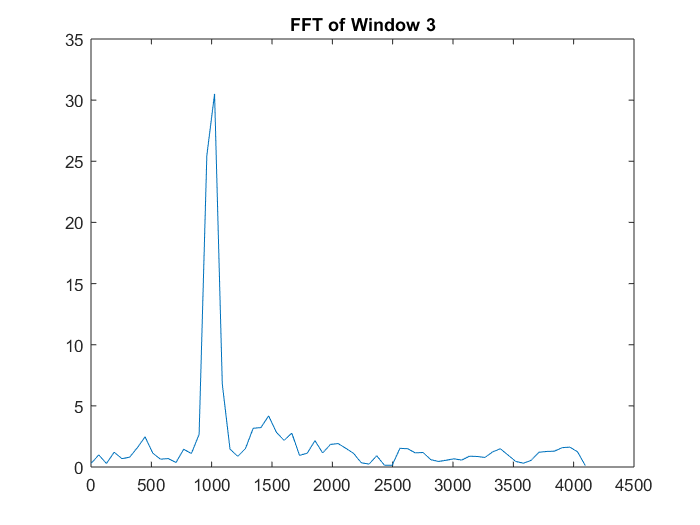

plot(f, w3Mag); title('FFT of Window 3')

### New Spectrogram with 75% Overlap

Our particular example of splat does include many short-lived signals, so the effect of adding overlap is a bit harder to see. However, if you compare the plot below with 75% overlap to that above with 0%, you will see that the plot changes more smoothly in time. Change the overlap in the code below and rerun the section to see the changes. 

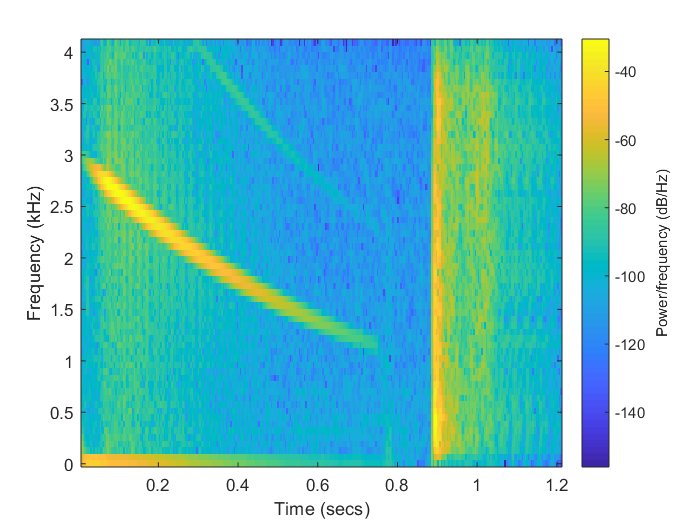

spectrogram(y, 128, 96, 128, Fs, 'yaxis')

### Considerations with Overlap

So why not set the overlap to 90, 95, or 99%? Notice in the example above, a 50% overlap increased the number of windows required from 2 to 3. As we increase the overlap, we increase the processing time to create the spectrogram. That's not too noticeable here (particularly as the recording is of low quality), but maybe you have home assistant or use voice commands on your phone? For live audio processing applications, speed is a concern and overlap must be taken into account.

## Number of Points in the FFT

The fourth input argument for the `spectrogram` function is the number of points to use when taking the Fourier transform. But wait, shouldn't that just be the number of points in the window? Why would they be different?

A common technique in signal processing is called zero-padding. Recall that the separation of points in the frequency domain is given by $Fs/N$. If N is small, as is the case for spectrograms, the separation between points is fairly large. To produce an improved visualization of the signal, we can pad the signal with zeros before taking the FFT. In fact, the `fft` function accepts a 2nd argument to do just that. 

### Illustration of Zero Padding

Let's go back to our example in the **Example of Overlapping Windows** section. 

plot(f, w2Mag); title('FFT of Window 2')

Now, let's redo the FFT, but zero pad the signal the signal out to 512 points. We can do this either by adding zeros to the signal itself or specifying 512 as the 2nd input argument to `fft`.

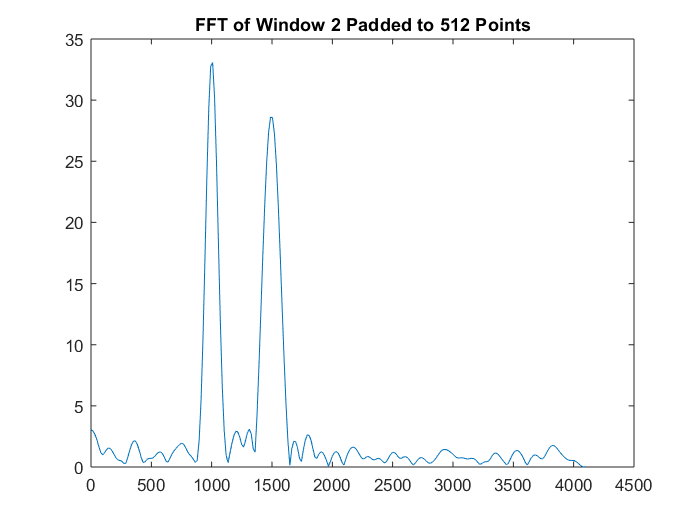

w2MagPadded = abs(fft(window2, 512));
% Create a new frequence axis for the padded FFT
f2 = 0:Fs/512:Fs/2;
w2MagPadded = w2MagPadded(1:length(f2));
plot(f2, w2MagPadded)
title('FFT of Window 2 Padded to 512 Points')

The resulting spectrum looks much cleaner and the peaks have of the shape we expect. Think of plotting a sine wave in MATLAB. If I only use 5 or 6 points, it may be difficult to tell that we've plotted a sine wave, but if you use a 100 points, the shape becomes more clear.

### So Zero Padding Increases Resolution?

No! Adding nothing but zeros to the end of a signal does not really increase our spectral resolution. We can still only resolve peaks separated by $Fs/N$ for which the data was acquired. Zero-padding allows us to "fill-in" some of the missing points so that the spectrum looks better. Just keep in mind that the actual resolution has not improved.

So why not always zero pad a lot? As with overlapping window, zero-padding increases the computational time and memory, so this can be a concern. A second concern is to not trick yourself (or others if presenting your data) to thinking the resolution is better than it is! In our spectrogram example, the frequency resolution is only 64 Hz. If we zero-pad to 512 points, the visualization would appear to have a resolution of 16 Hz if no information was known about how the data was acquired or processed. It's always important to record your processing steps!

### Zero-Padded Spectrogram

Let's recreate our spectrogram, only this time zero-pad the FFT to 512 points instead of the 128 we used previously.

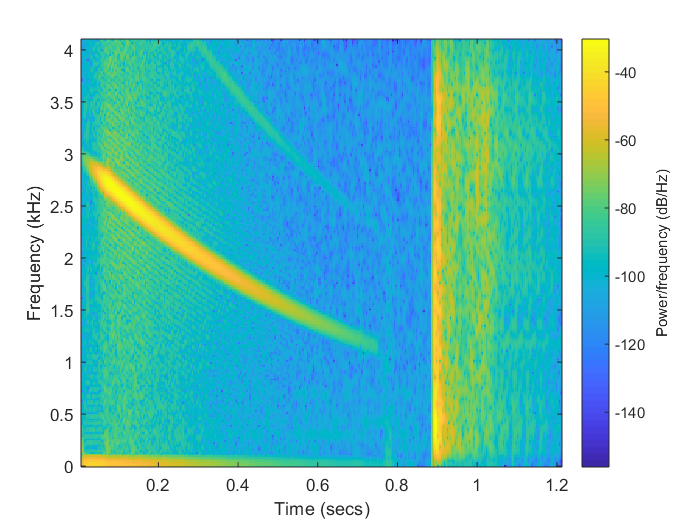

spectrogram(y, 128, 96, 512, Fs, 'yaxis')

Now this is a much better looking spectrogram than when we first started, and hopefully we learned a little bit about signal processing along the way!

## Odds and Ends

The fifth and sixth inputs to the spectrogram function are straightforward. By providing Fs, the function calculates the frequency axis (unlike how we manually do this with the `fft` function). The sixth input is optional and reverses the frequency and time axis. By default, the frequency axis is plotting along x and time along y. Depending on your preference or domain, you can reverse this as we did in all the above examples.

Finally, the `spectrogram` function can return the output data for us as well. When we request output arguments, a figure is not displayed, and we can use the output for further processing. One such application is using Machine Learning or Deep Learning techniques for voice recognition!